
clear variables;
[alldata786,queries786] = get_data_and_queries_786dim();

[alldata32,queries32] = get_data_and_queries_32dim();

% [gt_nns,gt_dists] = get_ground_truth_100_32();



pivots786 = alldata786(5:100,:);
witnesses786 = alldata786(101:600,:);
data786 = alldata786(1001:100000,:);
data32 = alldata32(1001:100000,:);


gt = euc(queries786(1,:),data786);



dims = 2; 

simp2 = NsimpProjection(pivots786,dims,@euc);

proj2 = zeros(size(data786,1),dims);
for i = 1 : size(data786,1)
    proj2(i,:) = simp2.project(data786(i,:));
end

qproj2 = simp2.project(queries786(1,:));


dims = 10; 

simp3 = NsimpProjection(pivots786,dims,@euc);

proj3 = zeros(size(data786,1),dims);
for i = 1 : size(data786,1)
    proj3(i,:) = simp3.project(data786(i,:));
end

qproj3 = simp3.project(queries786(1,:));


zDists2 = euc(qproj2,proj2);
zDists3 = euc(qproj3,proj3);
pDists = euc(queries32(1,:),data32);


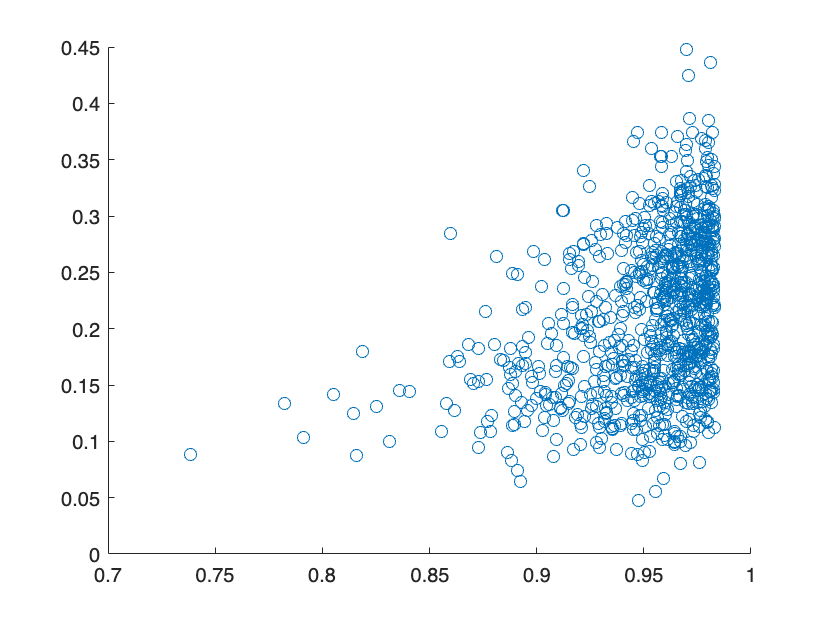


[smdists,ord] = sort(gt);

% plot(smdists,zDists(ord));
% plot(smdists,pDists(ord));




% 
% figure;
% hold on;
% scatter(zDists2(ord(1:1000)),gt(ord(1:1000)));
% scatter(zDists3(ord(1:1000)),gt(ord(1:1000)));
% legend("2","3");
% hold off;

scatter(gt(ord(1:1000)),zDists3(ord(1:1000)));

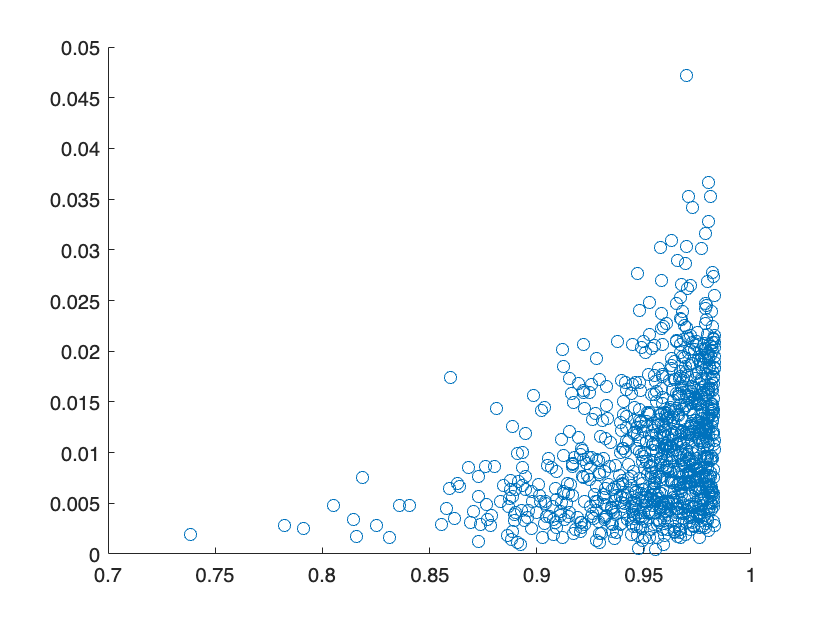



scatter(gt(ord(1:1000)),-zDists2(ord(1:1000)) .* (zDists2(ord(1:1000)) - zDists3(ord(1:1000))));


% scatter(pDists(ord(1:1000)),gt(ord(1:1000)));

